# Lab 04

# Machine Learning 

## SNS EE/CE 252L/251L-T2

Name: M Shees Abbas

ID: ma11212

# Task 1

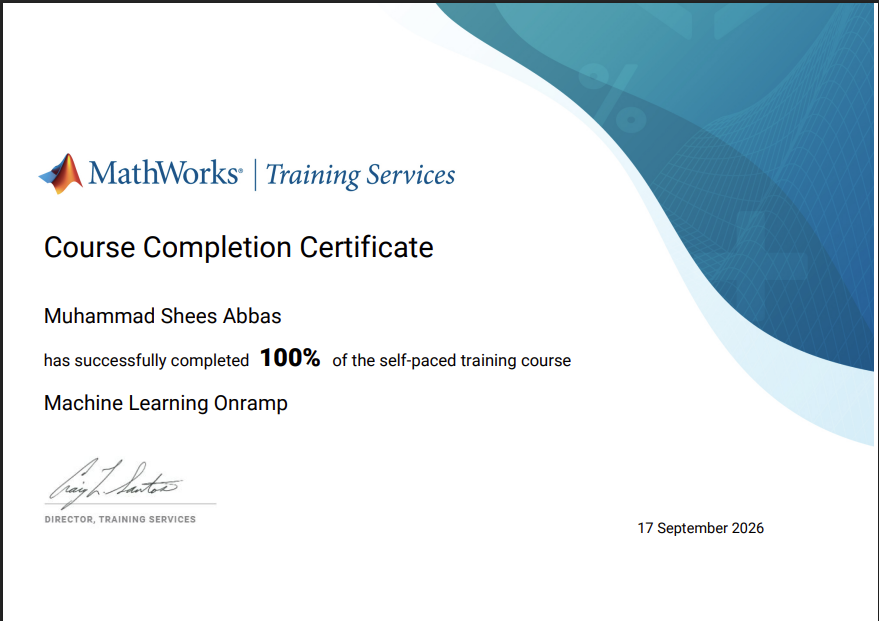

# Task 2

## step 1

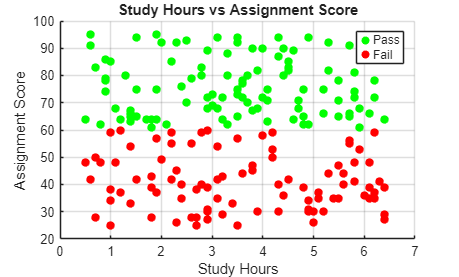

data = readtable("student_data.xlsx");
Result= categorical(data.Result);
passrow = Result == 'Pass';
failrow = Result == 'Fail';
figure;
scatter(StudyHours(passrow), AssignmentScore(passrow), 40, 'g', 'filled');
hold on;
scatter(StudyHours(failrow), AssignmentScore(failrow), 40, 'r', 'filled');
hold off;
xlabel('Study Hours');
ylabel('Assignment Score');
title('Study Hours vs Assignment Score');
legend('Pass','Fail');
grid on;

we used the scatter function to plot the graph because we didnt want a continious graph because we are not ploting these against time, and both of the components are discrete

## step 2

StudyHours = data.StudyHours;
Attendance = data.Attendance;
AssignmentScore = data.AssignmentScore;
input_data = [StudyHours,Attendance,AssignmentScore];

## step 3

norm_data = normalize(input_data, "zscore");

## step 4

split = cvpartition(Result, 'HoldOut',0.3)

split = Hold-out cross validation partition
    NumObservations: 200
        NumTestSets: 1
          TrainSize: 140
           TestSize: 60
           IsCustom: 0
          IsGrouped: 0
       IsStratified: 1


  Properties, Methods


Xtrain = split.training

Xtrain = 200×1 logical array
   1
   1
   1
   0
   1
   1
   1
   0
   0
   1
   0
   1
   1
   1
   1


r = data.Result

r = 200×1 cell array
    {'Pass'}
    {'Pass'}
    {'Fail'}
    {'Pass'}
    {'Fail'}
    {'Fail'}
    {'Pass'}
    {'Fail'}
    {'Fail'}
    {'Fail'}
    {'Pass'}
    {'Fail'}
    {'Fail'}
    {'Fail'}
    {'Fail'}
    {'Fail'}
    {'Fail'}
    {'Fail'}
    {'Fail'}
    {'Pass'}
    {'Pass'}
    {'Pass'}
    {'Pass'}
    {'Fail'}
    {'Pass'}
    {'Pass'}
    {'Pass'}
    {'Fail'}
    {'Pass'}
    {'Fail'}


Ytrain = r.training

Dot indexing is not supported for variables of this type.